% path = 'E:\Data\Aurelie\data\chroms\119\220923\registration\';
% path = "E:\Data\Aurelie\data\chroms\119\220919\registration_results_plan1_220919\";
path = "E:\Data\Aurelie\data\chroms\582\230331plane0\";
% path = "E:\Data\Aurelie\data\chroms\582\230331plane0\";
path_biapy = strcat(path,'biapy_centroids_matched.csv');
path_gcamp = strcat(path,'centroid_gcamp_affine.csv');
load("E:\Data\Aurelie\data\chroms\582\230331plane0\colorcell_biapy_raw.mat");

% === Calcul de la distance 3D entre centroides biapy et gcamp ===

% Chargement des CSV (skip de la ligne 1 = header)
biapy  = readmatrix(path_biapy,   'NumHeaderLines', 1);
gcamp  = readmatrix(path_gcamp,        'NumHeaderLines', 1);

% Colonnes : 1=Z, 2=X, 3=Y
z_b = biapy(:,1);  x_b = biapy(:,2);  y_b = biapy(:,3);
z_g = gcamp(:,1);  x_g = gcamp(:,2);  y_g = gcamp(:,3);

% Distance euclidienne 3D pour chaque cellule
distances = sqrt((x_b - x_g).^2 + (y_b - y_g).^2 + (z_b - z_g).^2);

% Affichage
n = numel(distances);
fprintf('Nombre de cellules : %d\n', n);

Nombre de cellules : 257


fprintf('Distance moyenne   : %.4f\n', mean(distances));

Distance moyenne   : 13.8475


fprintf('Distance min       : %.4f\n', min(distances));

Distance min       : 0.8688


fprintf('Distance max       : %.4f\n', max(distances));

Distance max       : 67.3343



% Export CSV résultat
cell_idx = (1:n)';
T = table(cell_idx, z_b, x_b, y_b, z_g, x_g, y_g, distances, ...
    'VariableNames', {'cellule','Z_biapy','X_biapy','Y_biapy', ...
                      'Z_gcamp','X_gcamp','Y_gcamp','distance_3D'});
writetable(T, 'distances_biapy_gcamp.csv');
fprintf('Résultat exporté dans distances_biapy_gcamp.csv\n');

Résultat exporté dans distances_biapy_gcamp.csv


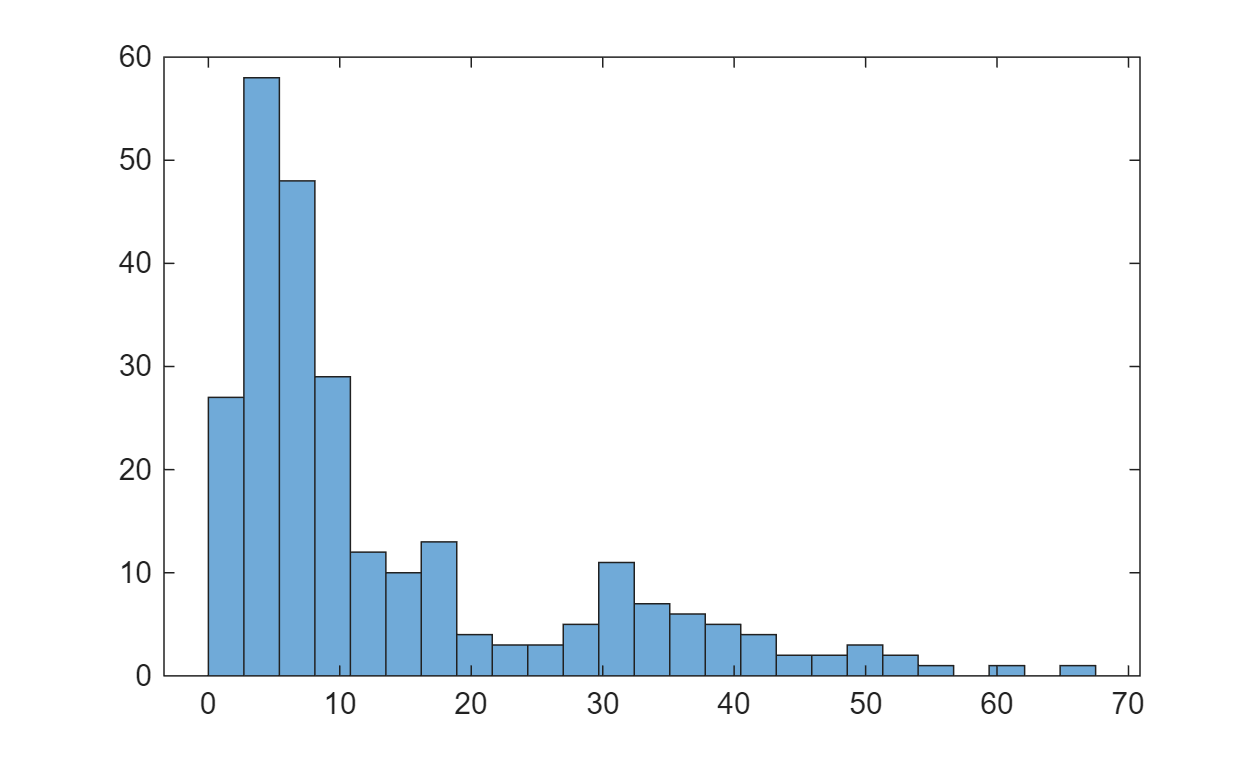


histogram(distances,25);


indices_sup = find(distances > 8);

fprintf('Nombre de cellules avec distance > 8 : %d\n', numel(indices_sup));

Nombre de cellules avec distance > 8 : 126


disp('Indices :');

Indices :


indices_sup

indices_sup =      5
    10
    14
    16
    17
    18
    19
    21
    22
    23
    26
    27
    29
    33
    35



% Affichage détaillé avec les distances correspondantes
fprintf('\nCellule\tDistance\n');


Cellule	Distance


for k = 1:numel(indices_sup)
    fprintf('%d\t\t%.4f\n', indices_sup(k), distances(indices_sup(k)));
end

5		18.1755
10		40.0212
14		8.2602
16		39.5388
17		9.0584
18		10.9374
19		17.7278
21		29.6739
22		9.7392
23		10.6014
26		8.9433
27		10.2433
29		27.5800
33		18.8669
35		30.6256
38		10.3153
43		23.6698
44		13.4440
45		38.5217
51		8.4533
53		36.6805
54		51.3252
55		35.6690
61		30.0083
62		31.7555
67		47.9530
68		8.1290
70		32.7592
73		19.5980
74		28.4273
77		8.9455
81		17.5742
83		30.8698
85		8.7384
86		15.8606
87		10.2810
89		9.0483
92		8.3553
94		13.1109
97		9.7749
98		32.8109
100		16.5609
101		12.6711
102		44.9253
104		67.3343
106		29.6105
108		48.9562
110		16.5513
112		15.6707
113		10.2809
114		31.3899
117		32.0412
119		35.8155
120		14.7798
122		12.0467
128		14.9749
133		17.6452
135		8.9818
136		8.7246
137		12.1052
138		14.1648
139		8.0551
140		35.8627
143		17.3126
144		54.6979
146		9.6265
148		26.0137
150		52.1215
151		22.9026
152		16.3622
153		15.6125
154		12.2619
156		12.6104
157		33.8028
158		8.3627
161		36.5487
163		31.2838
164		34.6012
165		9.3339
169		8.0829
170		17.5857
171		10

liste_binaire = double(distances < 8);
colorcell(liste_binaire==0) = 8;

% Distance euclidienne 2D pour chaque cellule

distances = sqrt((x_b - x_g).^2 + (y_b - y_g).^2 );

% Affichage
n = numel(distances);
fprintf('Nombre de cellules : %d\n', n);

Nombre de cellules : 257


fprintf('Distance moyenne   : %.4f\n', mean(distances));

Distance moyenne   : 7.8111


fprintf('Distance min       : %.4f\n', min(distances));

Distance min       : 0.1338


fprintf('Distance max       : %.4f\n', max(distances));

Distance max       : 56.6745



% Export CSV résultat
cell_idx = (1:n)';
T = table(cell_idx, z_b, x_b, y_b, z_g, x_g, y_g, distances, ...
    'VariableNames', {'cellule','Z_biapy','X_biapy','Y_biapy', ...
                      'Z_gcamp','X_gcamp','Y_gcamp','distance_3D'});
writetable(T, 'distances_biapy_gcamp.csv');
fprintf('Résultat exporté dans distances_biapy_gcamp.csv\n');

Résultat exporté dans distances_biapy_gcamp.csv


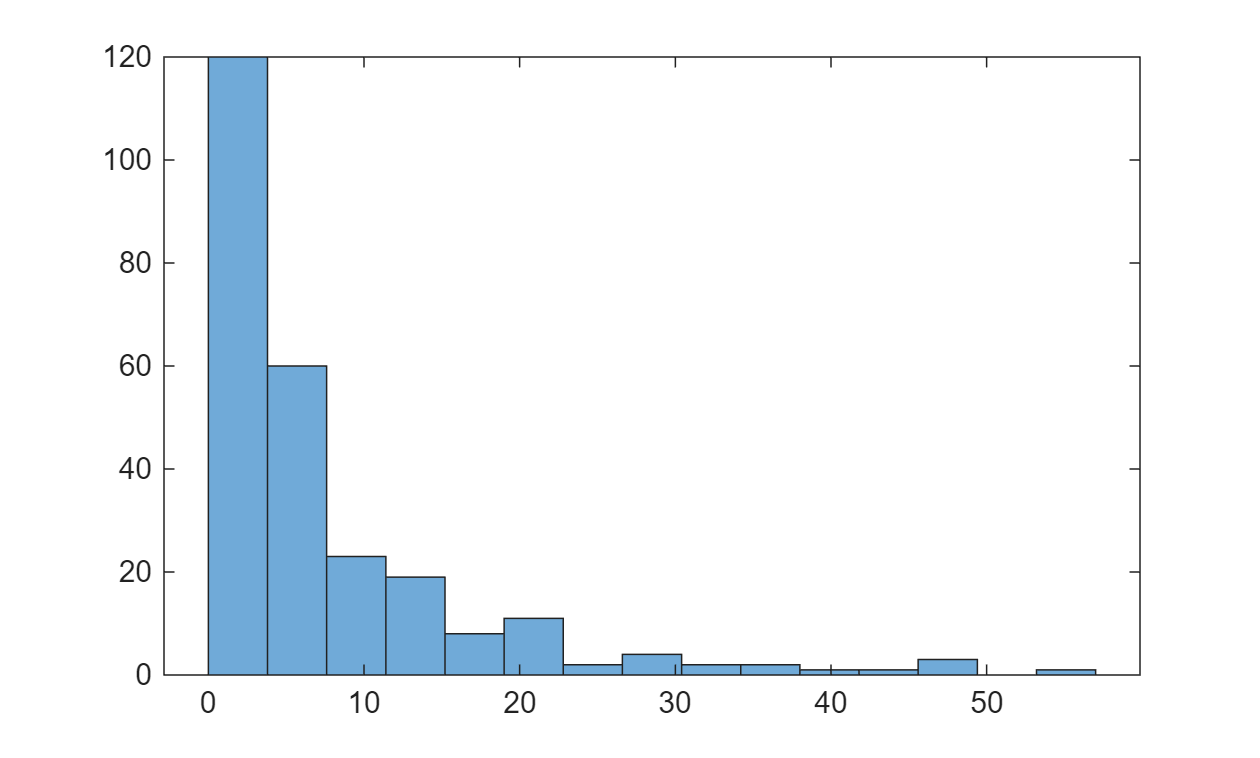


histogram(distances,15);


indices_supxy = find(distances > 4);

fprintf('Nombre de cellules avec distance > 10 : %d\n', numel(indices_supxy));

Nombre de cellules avec distance > 10 : 134


disp('Indices :');

Indices :


disp(indices_supxy);

     2
     3
     4
     5
     6
     8
    10
    14
    16
    17
    18
    19
    22
    23
    28
    29
    33
    34
    35
    36
    42
    43
    45
    51
    52
    53
    54
    55
    60
    61
    62
    67
    68
    69
    70
    73
    74
    77
    78
    80
    83
    84
    85
    86
    89
    90
    97
    98
   100
   102
   104
   106
   108
   110
   112
   113
   114
   117
   119
   121
   122
   125
   126
   127
   128
   133
   136
   137
   138
   139
   140
   144
   145
   146
   148
   150
   151
   153
   154
   155
   157
   158
   160
   161
   163
   164
   165
   166
   169
   171
   172
   174
   177
   181
   183
   184
   187
   188
   189
   192
   193
   195
   197
   198
   200
   201
   202
   207
   212
   213
   214
   215
   216
   217
   219
   221
   222
   223
   224
   225
   226
   228
   229
   230
   231
   232
   234
   236
   241
   245
   249
   252
   254
   257




% Affichage détaillé avec les distances correspondantes
fprintf('\nCellule\tDistance\n');


Cellule	Distance


for k = 1:numel(indices_supxy)
    fprintf('%d\t\t%.4f\n', indices_supxy(k), distances(indices_supxy(k)));
end

2		5.5822
3		4.7030
4		7.4754
5		9.3653
6		5.5768
8		6.2809
10		6.0276
14		7.2498
16		11.0088
17		6.4943
18		10.8353
19		10.7190
22		7.0156
23		7.9040
28		7.4448
29		17.3490
33		15.1976
34		4.5466
35		5.5315
36		4.5321
42		4.0514
43		11.5686
45		4.6782
51		6.2941
52		7.4317
53		17.7641
54		15.7441
55		29.9974
60		4.2183
61		9.1724
62		20.4502
67		34.7565
68		5.3648
69		7.0726
70		13.4205
73		13.7788
74		22.0729
77		7.9129
78		5.7520
80		7.8658
83		13.2334
84		4.5733
85		6.5942
86		14.2719
89		4.2477
90		6.3585
97		9.4769
98		11.0136
100		15.0987
102		26.9220
104		47.2015
106		11.4957
108		20.1162
110		4.9208
112		5.6281
113		5.3968
114		14.6969
117		20.8555
119		7.3211
121		5.2651
122		6.7424
125		4.8614
126		6.7479
127		4.0598
128		12.7480
133		9.1867
136		8.4416
137		11.8239
138		14.1614
139		8.0377
140		17.8921
144		28.8779
145		5.6429
146		9.6249
148		13.2069
150		46.8397
151		4.4030
153		15.6070
154		11.3152
155		6.5379
157		14.7174
158		4.5508
160		5.1149
161		33.3411
163		14.676

liste_binairexy = double(distances < 4);

colorcell(liste_binaire==0) = 8;
save (strcat(path,'colorcell_biapy_distance'),'colorcell')
disp('saved colorcell')

saved colorcell
